clear();

%载入音频资源
auFile='..\testresources\ゆびきり_drums_01.wav';
info = audioinfo(auFile)
[y,Fs]=audioread(auFile);

%显示音频波形
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
plot(t,y)
xlabel('时间')
ylabel('强度')

%进行FFT
L = 512;             %采样长度
P = 20624;

Y = abs(fft(y(P:P+L),L));

x_freq = [1:L/2]/L*Fs/1000;
y_freq = Y(L/2:L-1);


plot(x_freq/1000,y_freq)
xlabel('kHZ')
ylabel('振幅')

%对范围内连续FFT
clear('fftList');


L = 4096;%采样长度

ST=254;%开始位置(ms)

ET=20000;%结束位置(ms)

FT=20;%fft帧时间(ms)

fftList=zeros(L/2,int64((ET-ST)/FT));%FFT帧数据
%fList=zeros(int64((ET-ST)/FT),1);%降维后的数据



for i=1:(ET-ST)/FT
    %进行FFT

    clear('P','Y','x_freq','y_freq');


    P =(Fs/1000*ST)+ i*int64(Fs/1000*FT);%采样位置

    Y = abs(fft(y(P:P+L),L));%FFT

    x_freq = (1:L/2)/L*Fs;
    y_freq = Y(1:L/2);%取半




    fftList(:,i)=y_freq;

    %fList(i)=sum(y_freq(:))

end

fList=sum(fftList)

fList = 1.0e+04 *

   0.001231264746040   0.002996345380312   0.009652483905127   0.032486044082747   0.034769305243662   0.034747243054840   0.035082199779411   0.023818928069029   0.017376307491778   0.010932875984976   0.011424931900234   0.013299804915143   0.015125953320281   0.017437976880850   0.018930551853699   0.022142274040065   0.024947240450920   0.025442231903364   0.029865667701099   0.033676242731963   0.046576283580974   0.093577942100151   0.115666635212137   0.116037418743669   0.121655773683384   0.112114009164751   0.106185066785075   0.090381149530215   0.097596461488332   0.106188740747739   0.119774990890801   0.134834719325671   0.151341794470467   0.173813899152111   0.186084455810507   0.205201488208396   0.228126645215762   0.245553646729626   0.328184004602448   0.410892321273889   0.459000057323114   0.485016941089885   0.494500428921352   0.498496241098784   0.475885437171917   0.477660347787584   0.476628263558954   0.526516967180419   0.557158219062472 

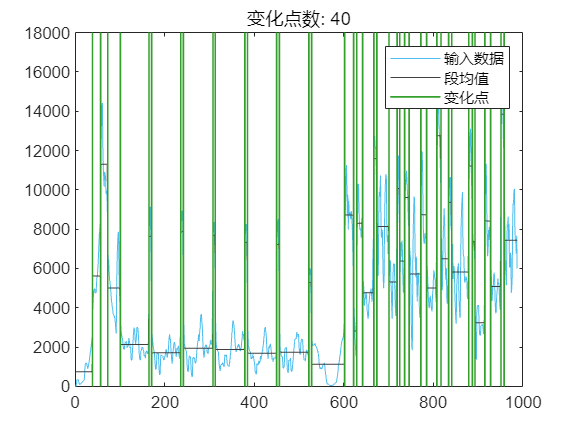

% 查找变化点
[changeIndices,segmentMean] = ischange(fList,"MaxNumChanges",40);

% 显示结果
figure
plot(fList,"Color",[77 190 238]/255,"DisplayName","输入数据")
hold on

% 绘制变化点之间的线段
plot(segmentMean,"Color",[64 64 64]/255,"DisplayName","段均值")

% 绘制变化点
x = repelem(find(changeIndices),3);
y2 = repmat([ylim(gca) missing]',nnz(changeIndices),1);
plot(x,y2,"Color",[51 160 44]/255,"LineWidth",1,"DisplayName","变化点")
title("变化点数: " + nnz(changeIndices))

hold off
legend

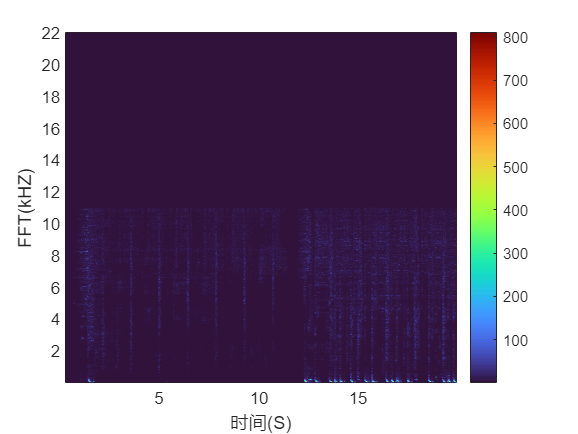

clear segmentMean x y2

pcolor((ST/FT:ET/FT-1)*FT/1000,x_freq/1000,fftList);
shading interp;
colorbar;
colormap("turbo");
xlabel('时间(S)')
ylabel('FFT(kHZ)')

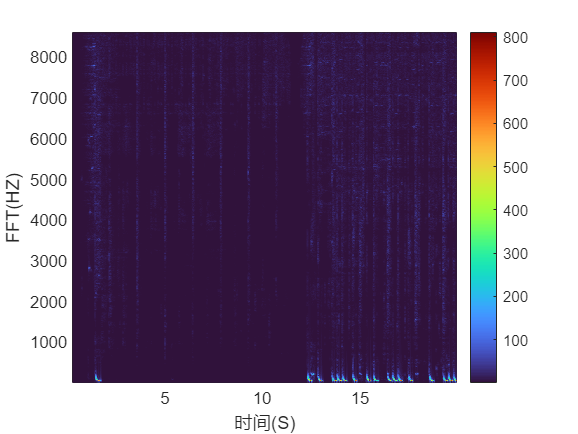



pcolor((ST/FT:ET/FT-1)*FT/1000,x_freq(1:800),fftList(1:800,:));
shading interp;
colorbar;
colormap("turbo");
xlabel('时间(S)')
ylabel('FFT(HZ)')

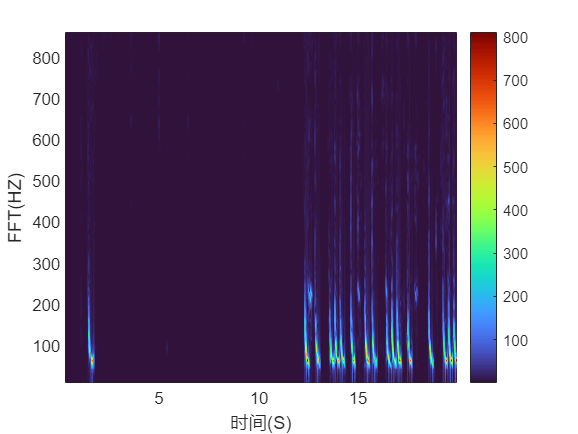




pcolor((ST/FT:ET/FT-1)*FT/1000,x_freq(1:80),fftList(1:80,:));
shading interp;
colorbar;
colormap("turbo");
xlabel('时间(S)')
ylabel('FFT(HZ)')

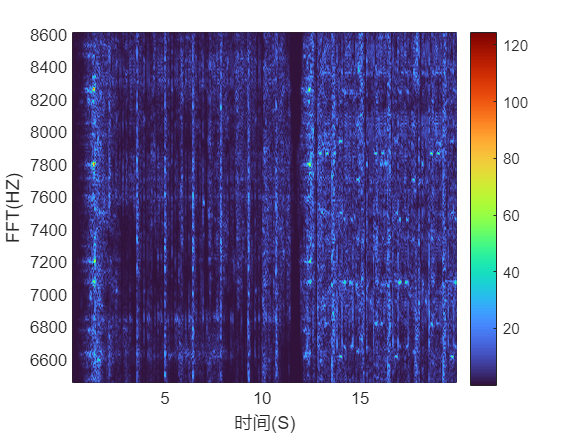



pcolor((ST/FT:ET/FT-1)*FT/1000,x_freq(600:800),fftList(600:800,:));
shading interp;
colorbar;
colormap("turbo");
xlabel('时间(S)')
ylabel('FFT(HZ)')

disp(detectBPM(auFile))

   NaN
   NaN


function [BPM, beats] = detectBPM(audio_path)
% 使用自适应阈值的基于能量的方法检测音频的BPM值
% 参数:
%   audio_path: 音频文件路径
% 返回值:
%   BPM: 估计的BPM值
%   beats: 所有检测到的拍点位置，单位为采样点数

% 读取音频文件
[audio, Fs] = audioread(audio_path);

% 将音频转换成单声道
audio = mean(audio, 2);

% 设置参数
win_size = 4410; % 分析窗口大小
step_size = 2205; % 步长
min_energy = 0.1; % 最小能量阈值
decay_rate = 0.999; % 能量衰减率
min_bpm = 60; % 最小BPM值
max_bpm = 240; % 最大BPM值
decimation_factor = 4; % 降采样因子
fft_size = 2^nextpow2(win_size/2); % FFT大小

% 计算能量
energy = zeros(length(audio), 1);
for i = 1:win_size:length(audio)-win_size+1
    frame = audio(i:i+win_size-1);
    energy(i:i+win_size-1) = energy(i:i+win_size-1) + frame.^2;
end



% 避免分母为0
if max(energy) == 0
    predict = 1;
    return
end

% 对能量进行归一化
energy = energy / max(energy);
if any(isnan(energy))
    energy(isnan(energy)) = 0;
end


% 自适应阈值处理
mean_energy = movmean(energy, win_size, 'Endpoints', 'discard');
threshold = mean_energy * min_energy;

% 能量衰减处理
for i = 2:length(energy)
    energy(i) = max(energy(i)*decay_rate, energy(i-1));
end

% 通过能量的差值判断大概的起始拍点
[~, predict] = max(diff(energy));
predict = predict + round(win_size/step_size);

% 继续向下检测拍点
beats = zeros(length(audio), 1);
correct = 0;
step = round(Fs*60/max_bpm/step_size);

for i = predict:step:length(audio)-win_size+1
    if energy(i) > threshold(i)
        if energy(i) > energy(i+step) && energy(i) > energy(i-step)
            correct = correct + 1;
            beats(correct) = i;
        end
    end
end
beats = beats(1:correct);

% 将两个不准确的拍点预测下一个拍，判断是否准确
for i = 3:correct-1
    interval1 = beats(i) - beats(i-2);
    interval2 = beats(i+1) - beats(i-1);
    if abs(interval1 - interval2) < 0.1 * mean([interval1, interval2])
        beats(i) = (beats(i-1) + beats(i+1)) / 2;
    end
end

% 计算BPM值
BPM = 60 / (mean(diff(beats)) + eps) * Fs / decimation_factor;

% 打印结果
disp(BPM);

end

